# Fluid descriptions

[⇦ Overview](matlab:open('./Overview.m'))

Fluid material are continuous substance composed of a very large number of particle that do not display of fixed shape. Both liquids and gases are generics type of fluids that diplay one major difference. Gas 

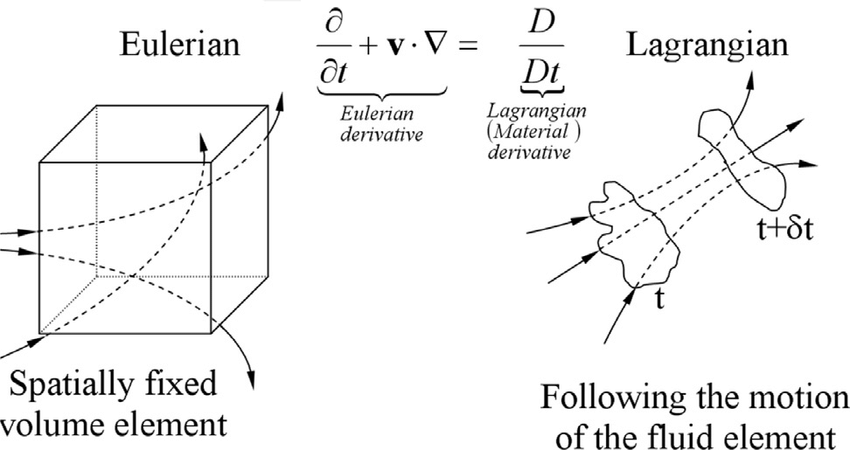

Conservation law: in an isolated system, measurable physical property does not change as the system evolves with time.

## Icon that can be used

  **Try**.

  **Pro-tip**.

** Demonstration**.

 **Reflect**.

** Application.**

## How to describe a fluid?

Fluid mechanics is a branch of mechanics that is more globally under the continuum mechanics. In continuum mechanics, fluids are modeled using fluid parcel of continuous mass composed of many particle instead of tracking each individual discrete particle. This assumption is assumed for two reasons: the 

### Lagrangian description of fluid

The Lagrangian description of fluid is the tracking with respect to time of the position of the fluid parcels. Imagine a random fluid particle in a open volume of fluid of 1 m side (in two dimension)

t = 0.0;

figure()
axis equal
xlim([0 1])
ylim([0 1])
hold on

xp = [0.5 0.5];
u  = rand(2,1)-[0.5; 0.5];

scatter(xp(1), xp(2), 10, 'filled', 'SeriesIndex', 1);
quiver(xp(1), xp(2), u(1), u(2))
text(xp(1)+0.05, xp(2), 't = 0')

Next time frame


dt = 0.5 ;
t = t + dt;
xp = xp + dt*u;
u  = u + 0.3*(rand(2,1)-[0.5; 0.5]);

scatter(xp(1), xp(2), 10, 'filled', 'SeriesIndex', 1);
quiver(xp(1), xp(2), u(1), u(2))
text(xp(1)+0.05, xp(2), "t = "+num2str(t))

  **Try plotting a streamline over 3 s**

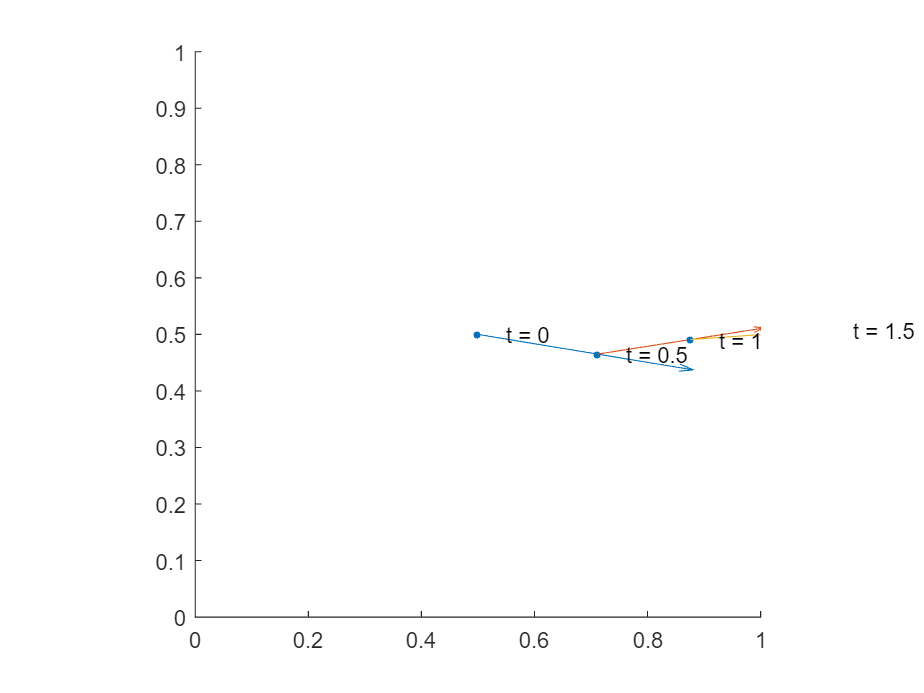

for i = 1:5
    dt = 0.5;
    t = t + dt;
    xp = xp + dt*u;
    u  = u + 0.3*(rand(2,1)-[0.5; 0.5]);
    
    scatter(xp(1), xp(2), 10, 'filled', 'SeriesIndex', 1);
    quiver(xp(1), xp(2), u(1), u(2))
    text(xp(1)+0.05, xp(2), "t = "+num2str(t))
end
hold off 

 **Reflect**. How feasible does it sounds for a very large number of fluid parcel?

### Eulerian description of fluid

phi(x,t)

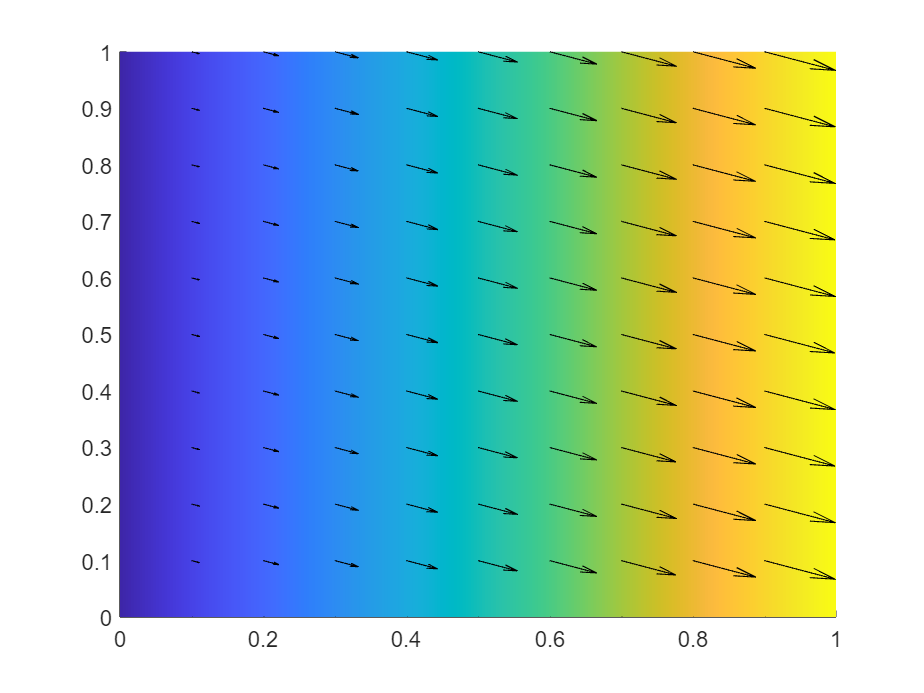

x = 0:0.1:1;
y = 0:0.1:1;
[xg, yg] = meshgrid(x,y);

t = 0.0;
fx = @(x,y,t)  0.3*x+0.1*t*sqrt(x.^2+y.^2);
fy = @(x,y,t) -0.1*x;

figure()
hold on 
xlim([0 1])
ylim([0 1])

ux = fx(xg,yg,t);
uy = fy(xg,yg,t);
u = sqrt(ux.^2+uy.^2);
contourf(x,y,u,256, 'LineColor', 'none')
quiver(xg, yg, ux, uy, 'Color', 'k')

 **Reflect**. Think about how Eulerian and Lagrangian experimental setup might look like?

Eulerian: doppler, thermometer, etc.

Lagrangian: Atmospheric balloon

** Application.**

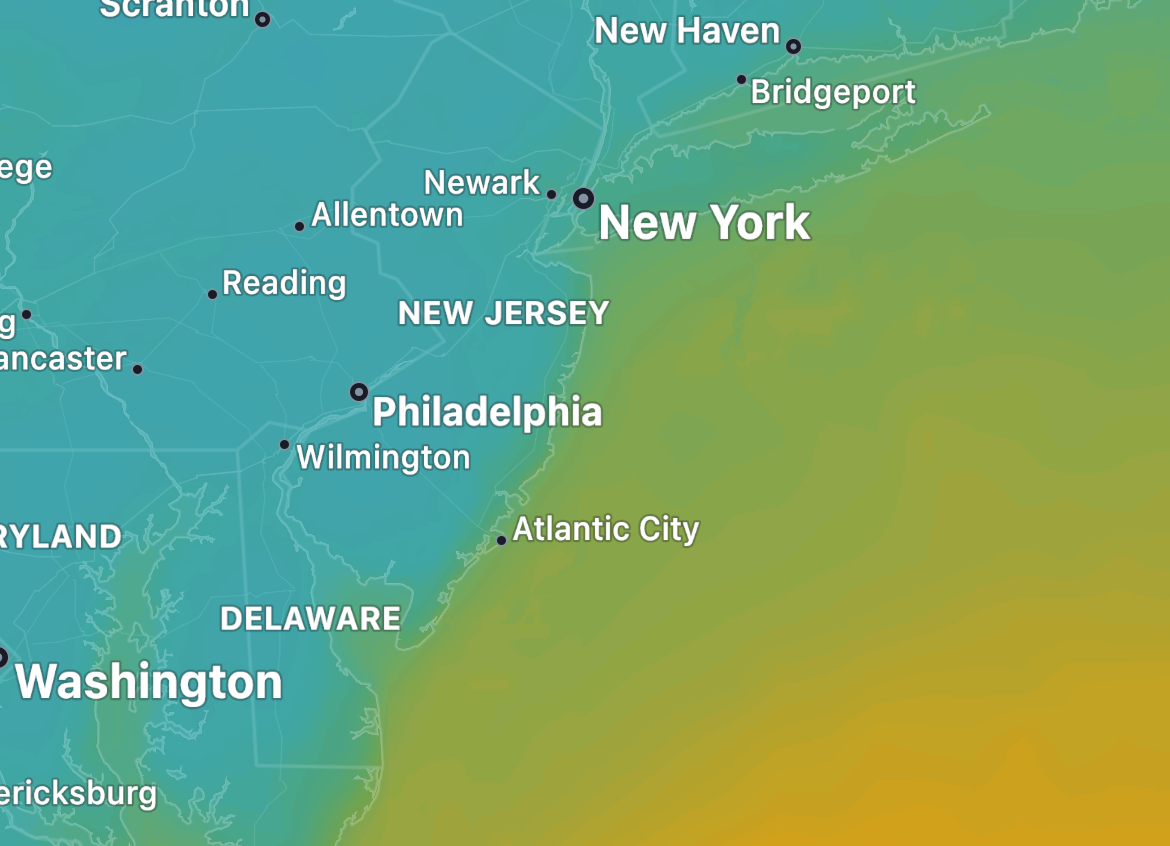

## Link in between Eulerian and Lagrangian

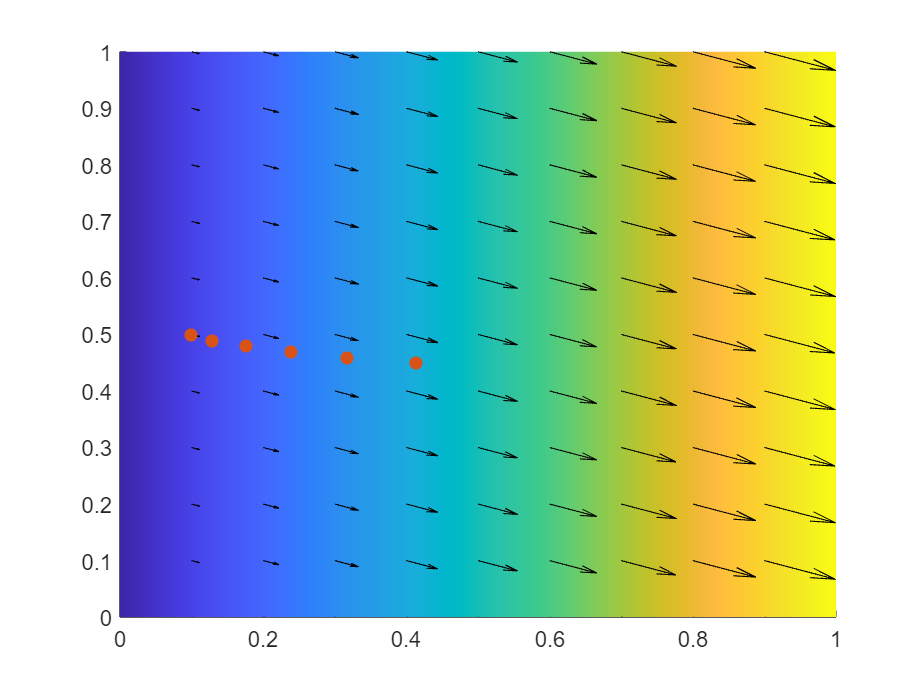

x0 = [0.1 0.5];
scatter(x0(1), x0(2), 'filled', 'SeriesIndex', 2)
dt = 1.0;
for i = 1:5
    t = t + dt;
    x0 = [x0; x0(end,:) + dt*[fx(x0(1),x0(2),t-dt) fy(x0(1),x0(2),t-dt)]];
end

scatter(x0(:,1), x0(:,2), 'filled', 'SeriesIndex', 2);
hold off

## Material derivative

% scatter(0.5, 0.5, 20, 'filled', 'SeriesIndex', 2)
% hold on
x = 0:0.2:1;
[X,Y] = meshgrid(x, x);
Z = X+Y;
pcolor(X,Y,Z, '')

Error using pcolor
Too many input arguments.

xlim([0 1])
ylim([0 1])
hold on
scatter3(0.5,0.5,0.10, 20, 'filled', 'SeriesIndex',2)
hold off

T = interp2(X,Y,Z,0.5, 0.5);
for i = 1:10
    X = X + 0.1;
    T(end+1) = interp2(X,Y,Z,0.5, 0.5);
end

plot(T)


 **Reflect**. For many applications the Eulerian description is more much convenient than the Lagrangian description. 

Physical properties of the system such as temperature, mass, density, or really anything is hold on the fluid particle wether than the grid.

syms phi(x,t) dt dx u

DPhiDt = ( phi(x+u*dt, t+dt) - phi(x,t) ) / dt
PhiB = phi(x,t) + dt * diff(phi,t) + dx*diff(phi,x)
PhiA = phi(x,t);
DPhiDt = expand((PhiB - PhiA)/dt)


$$\frac{D\Phi}{Dt} = \frac{\partial \Phi}{\partial t} + {\bf u} \cdot \nabla\Phi\\

\frac{D}{Dt} \equiv \frac{\partial }{\partial t} + {\bf u} \cdot \nabla \\

$$



$$\nabla \equiv \;\left\lbrack \begin{array}{c}
\frac{\partial \;}{\partial x}\\
\frac{\partial \;}{\partial y\;}\\
\frac{\partial \;}{\partial z}
\end{array}\right\rbrack$$


## Reynolds Transport Theorem


$$\int(\nabla\cdot {\bf F})dV=\int ({\bf F}\cdot{\bf n})dS$$


1 - Derive the Reynolds transport therorem

2 - Ask to apply the theorem to mass -> conservation of mass

3 - Conservation of energy?

[⇦ Return to the navigation page](matlab: OpenOverview)